# Reset File Position Indicator

Open the following file, perform a read operation, and then move the file position indicator back to the beginning of the file.

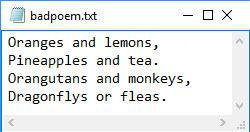

Use `fopen` to open the file, and then use `fgetl` to read the first two lines.

fid = fopen('badpoem.txt');
tline1 = fgetl(fid)  % read first line 
tline2 = fgetl(fid)  % read second line

The previous two read operations moved the position indicator to the beginning of line `3` in the poem. As a result, the next read operation using `fgetl `returns line `3`. 

tline3 = fgetl(fid)

To reread the first line of the file, reset the position indicator using the `frewind` function, and then perform the read operation.

frewind(fid)
fgetl(fid)

Close the file.

fclose(fid);

*Copyright 2012 The MathWorks, Inc.*